# **3D image processing** **using 3D-DST and GPUarray**

This example shows how to process an colour image using the three-dimensional discrete sine transform (3D DST).

Read an image into the workspace, then convert the image to double.

[X, map] = imread ('corn.tif');
if ~isempty (map)
    Im = ind2rgb(X, map);
end
whos Im

  Name        Size                 Bytes  Class     Attributes

  Im        415x312x3            3107520  double              



Perform a 3D DST of the colour image using the `Discrete_Transform_3D` function.

Im=gpuArray (Im);
J = Discrete_Transform_3D (Im, 'sine', 'direct', 'two', 'row');

Reconstruct the image using the inverse 3D DST function `Discrete_Transform_3D`.

K = Discrete_Transform_3D (J, 'sine', 'inverse', 'two', 'row');

Display the original colour image alongside the processed image.

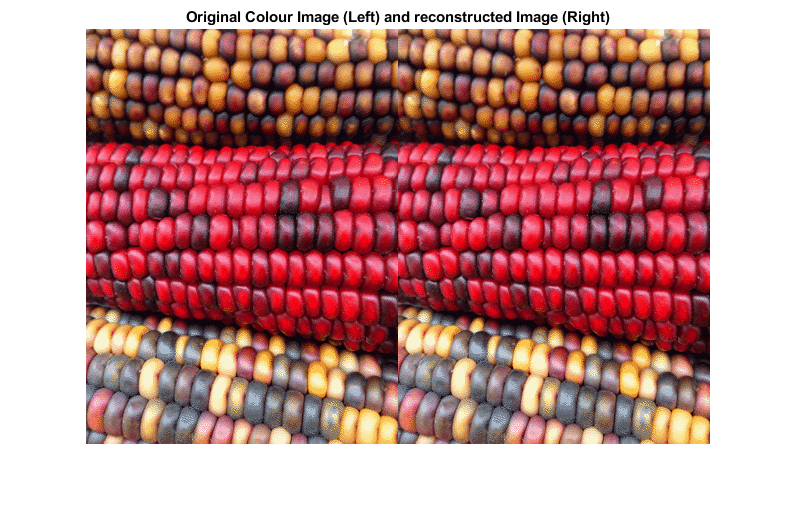

K=gather (K);
Im=gather (Im);

figure
imshowpair(Im, K,'montage')
title('Original Colour Image (Left) and reconstructed Image (Right)');